## Stat exam prep & general help

- notes

clc; clear;

% data = xlsread("Data_M4STI1_2017E.xlsx", 'K:L');
data = readtable("Data_M4STI1_2017E.xlsx")

data = 60×12 table
    Opg1_Bremsefabrikat    Opg1_Koerer    Opg1_Daektype    Opg1_Bremseevne    Var5    Opg2_Temperaturintervaller_tekst    Opg2_Temperaturintervaller_nr    Opg2_ObserveretAntal    Var9    Opg3_Nr    Opg3_Brembo    Opg3_CI
    ___________________    ___________    _____________    _______________    ____    ________________________________    _____________________________    ____________________    ____    _______    ___________    _______

             1                  8               1                1459         NaN            {'t<150'         }                   



opg3_brembo = rmmissing(table2array(data(:,"Opg3_Brembo")));
opg3_cl = rmmissing(table2array(data(:, "Opg3_CI")));

deskripts(opg3_brembo',"Brembo")

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Brembo"      92.798       0.67258         0.82011             20     



deskripts(opg3_cl',"Brembo")

    Datanavn    Middelværdi    Varians    Standardafvigelse    Målepunkter
    ________    ___________    _______    _________________    ___________

    "Brembo"      92.913       6.8375          2.6149              20     



## Visuals

rng(2)
randmat = [2.2:0.1:3.5, 3.6, 4.2:0.1:5.2];

stemleafplot(randmat, -1)

  2 | 2 3 4 5 6 7 8 9
  3 | 0 1 2 3 4 5 6
  4 | 2 3 4 5 6 7 8 9
  5 | 0 1 2
key: 36|5 = 36.5
stem unit: 1.0
leaf unit: 0.1


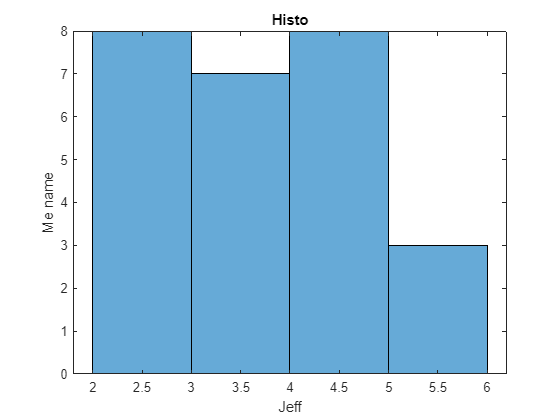


figure
h = histogram(randmat, 2:1:6);

title("Histo")
xlabel("Jeff")
ylabel("Me name")

### Histo med categorical

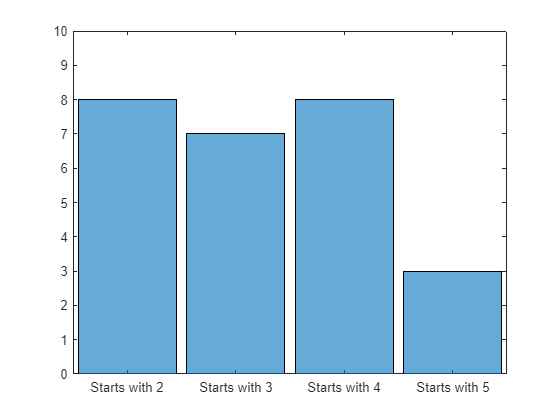

figure

cat = categorical(floor(randmat), [2, 3, 4, 5], ["Starts with 2","Starts with 3","Starts with 4","Starts with 5"]);

histogram(cat)
ylim([0,10])

## Fucking boxplots

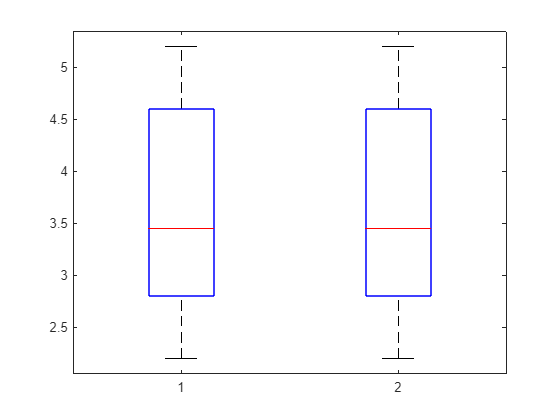

figure
boxplot([randmat',randmat'])

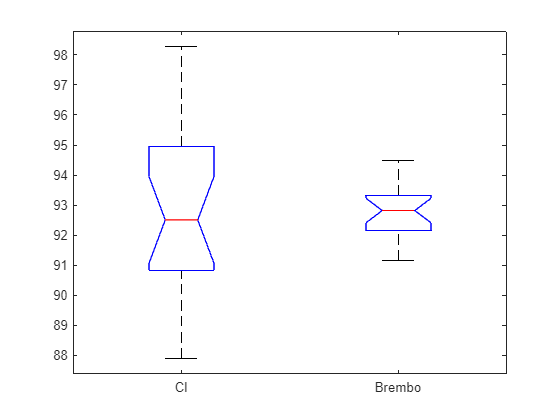


% Brembo og Cl
figure
boxplot([opg3_cl, opg3_brembo],["Cl","Brembo"],"Notch","on")

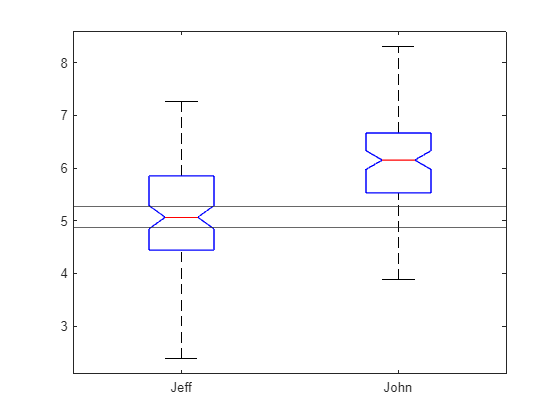

% normrnd data
n1 = normrnd(5,1,100,1);
n2 = normrnd(6,1,100,1);

figure
boxplot([n1,n2], ["Jeff","John"],"Notch","on")

hold on
yline(h(1))
yline(h(2))
hold off

[d,g,h,j]=ztest(n1, 5,1,"Alpha",0.05)

d = 0

g = 0.2615

h =     4.9163
    5.3083


j = 1.1227

Frihedsgradernes formel


$$\mathrm{df}=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$t_{\mathrm{df},\alpha }=-\mathrm{tinv}\,\alpha \,\mathrm{df}$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}-\delta }{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------
    Datanavne    Middelværdier    Spredning    standardafv.    Datapunkter
    _________    _____________    _________    ____________    ___________

    "Input 1"       92.798         0.67258       0.82011           20     
    "Input 2"       92.913          6.8375        2.6149           20     

    Frihedsgrader    Pooled varians    Pooled spredning    Grænse    Teststatistik    p-værdi    h-værdi
    _____________    ______________    ________________    ______    _____________    _______    _______

         38  

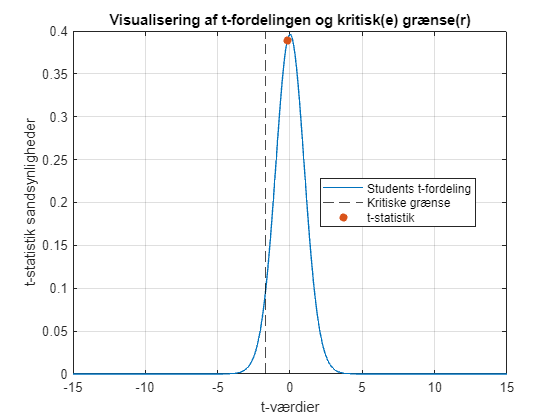

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at t-værdien -0.18718 ikke overstiger den kritiske grænse på -1.686


ans = struct with fields:
    stats: [1×1 struct]
        p: 0.4263
       ci: [2×1 double]



ttest2popMiddelInd_Test4(opg3_brembo, opg3_cl, "left",95, 0)